## Project 9B: Identification of brain areas associated with the execution of an action

Authors: **Giovanni Canini, Simone Migliazza**

clc
clear all
close all

### Intro

Blood Oxygen Level Dependent (BOLD) functional magnetic resonance imaging (fMRI) depicts changes in deoxyhemoglobin concentration consequent to task-induced or spontaneous modulation of neural metabolism [1]. Since its inception in 1990, this method has been widely employed in thousands of studies of cognition for clinical applications [1].

Neuroimaging researchers increasingly take advantage of the known functional properties of brain regions to localize activation regions in the brain and investigate changes in their activity under various conditions [2]. Using this noninvasive functional MRI (fMRI) method makes it possible to identify and localize brain activation [2].

In this experiment, a sequence of resonance image acquisitions of the temporal evolution of the volumetric distribution of oxyhemoglobin concentraion, is taken during the execution of a mental task. 

The experimental protocol consists of 'active' phases in which the subject have to read a word and think about its synonyms and antonyms, and 'passive' phases in which the subject remains at rest. We want to identify the brain regions involved in this mental task   (those in which the concentration of oxyhemoglobin changes between the resting and active phases).

We solve this problem as a regression problem, considering the correlation between the hemodynamic response function (HRF) and the resonance image acquisitions.

### **Reading the data**

relpath = "../";
v = zeros(128, 128, 18, 40);
for i=1:40
    tmp = analyze75read(relpath + sprintf("data/VOL%02d.img", i));
    tmp(isnan(tmp)) = 0;
    v(:, :, :, i) = tmp;
end

### **Excluding all the voxels that are not part of the brain**

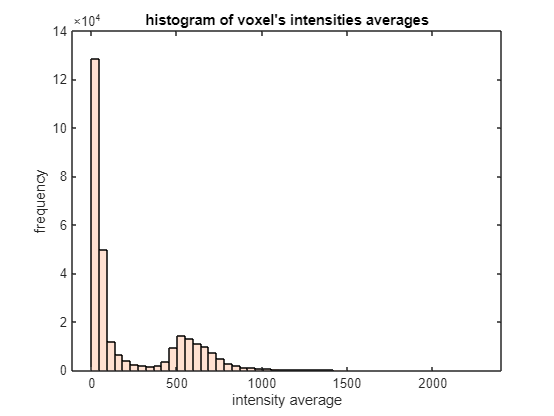

avg = mean(v,4); % average along the time dimension
gram = histogram(avg(avg > 0), 50);
gram.FaceColor = [1, 0.8, 0.7];
xlabel("intensity average")
ylabel("frequency")
title("histogram of voxel's intensities averages")

In the histogram we can see that voxels which the intensity average is below 300 are the one that are not part of the brain.

mask = avg > 300;

Another thing that we can do is put ones in the mask if all neighbours are ones, and zeros if all are zeros.

kernel = ones(3, 3, 3);
neighbor_sum = convn(mask, kernel, 'same'); % contains the sum of all the values in the neighborhood for each voxel in mask
mask(neighbor_sum == 26) = 1; % if all the neighbors are 1s becomes 1
mask(neighbor_sum == 0) = 0;  % if all the neighbors are 0s becomes 0

Applying the mask:

for i=1:40
    v(:, :, :, i) = v(:, :, :, i).*mask;
end

Checking the result:

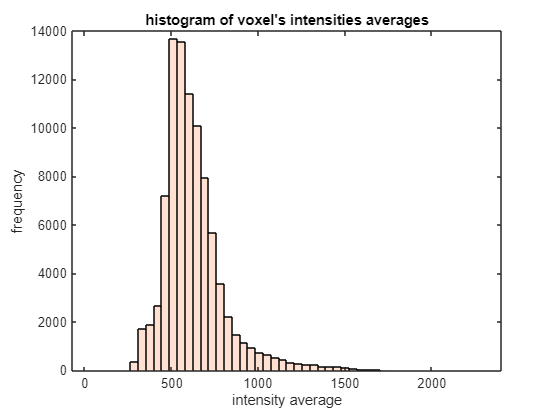

figure;
avg = mean(v,4);
gram = histogram(avg(avg > 0), 50);
gram.FaceColor = [1, 0.8, 0.7];
xlabel("intensity average")
ylabel("frequency")
title("histogram of voxel's intensities averages")

clear avg gram i kernel mask neighbor_sum tmp;

### **Defining the hemodynamic response function (HRF)**

activation = repmat([ones(1,20), zeros(1,20)], 1, 4);

The HRF waveform is modelled by poisson, Gaussian function and difference of gamma functions [3]. Here, the widely used difference of gamma function model is used and it can be represented by:


$$h\left(t\right)={\left(\frac{t}{d_1 }\right)}^{a_1 } \exp \left(\frac{-\left(t-d_1 \right)}{b_1 }\right)-{c\left(\frac{t}{d_2 }\right)}^{a_2 } \exp \left(\frac{-\left(t-d_2 \right)}{b_2 }\right)$$


where $d_i =a_i {*b}_i$ represents the amplitude of the peak and c represents the undershoot. The normally used parameters are a1 = 6, a2 = 12, b1 = b2 = 0.9, and c = 0.35 [4].

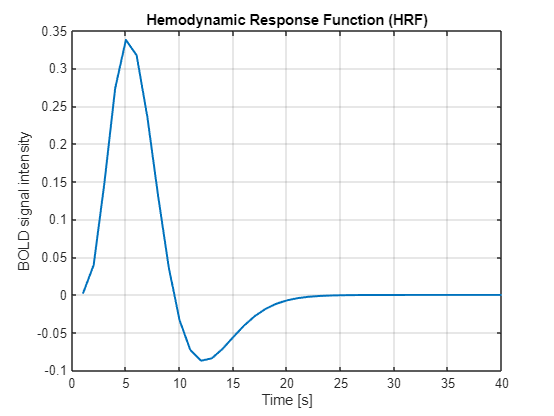

t = 1:40;
h = hrf(t, 6, 12, 0.9, 0.9, 0.35);
h = h / trapz(h); % make unit the area under the curve 

figure;
plot(t, h, 'LineWidth', 1.5);
title('Hemodynamic Response Function (HRF)');
xlabel('Time [s]');
ylabel('BOLD signal intensity');
grid on;

### **Convolution with the activation profile to determine the expected blood oxygen level response**

convolved_signal = conv(h,activation, 'full');
convolved_signal = convolved_signal(1:length(t));
convolved_signal = repmat(convolved_signal, 1, 4);

Checking the result:

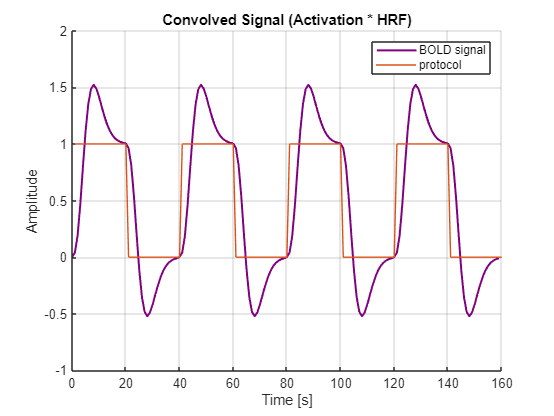

t= 0:1:159;
figure;
hold on
plot(t, convolved_signal, 'LineWidth', 1.5, "Color", [0.5, 0, 0.5]);
title('Convolved Signal (Activation * HRF)');
xlabel('Time [s]');
ylabel('Amplitude');
grid on;
plot(activation)
legend(["BOLD signal", "protocol"])

### Regress against the sequence of activations of each voxel

convolved_signal = convolved_signal(5:end); % reject the first data as requested
us_convolved_signal = convolved_signal(1:4:end); % undersampling the signal every 4 seconds
X = [us_convolved_signal', ones([39 1])];
corr = zeros(128, 128, 18); % correlation coefficient
p = ones(128, 128, 18); % p-value
f = zeros(128, 128, 18); % fisher

parfor x = 1:128
    for y = 1:128
        for z = 1:18
            Y = squeeze(v(x,y,z,2:end));
            if nnz(Y) > 0
                [~, ~, ~, ~, stats] = regress(Y, X); 
                corr(x, y, z) = stats(1);
                f(x, y, z) = stats(2);
                p(x, y, z) = stats(3);
            end
        end
    end
end

The median filter is used to reduce noise while preserving the edges of activation regions, making it particularly suitable for fMRI data where we aim to eliminate isolated false positives without overly smoothing the spatial structure of the signal.

p = medfilt3(p, [3 3 1]);
corr = medfilt3(corr, [3 3 1]);
clear activation convolved_signal h stats t us_convolved_signal x X y Y z;

### Display of the voxels that exhibit a significant correlation

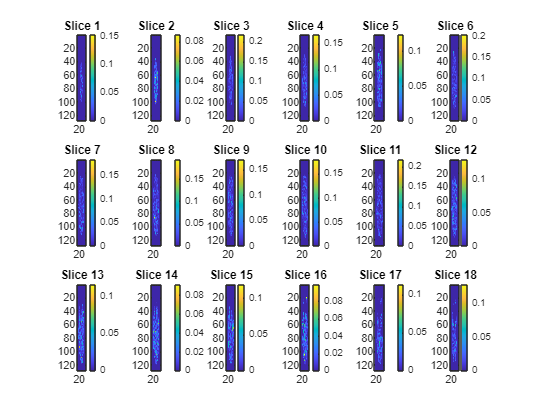

figure;
title('Spatial Map of Voxel-Activation Correlation'); % N.B: open it in full screen
for slice = 1:18
    subplot(3, 6, slice); 
    imagesc(corr(:, :, slice)); 
    colorbar;
    %clim([0 0.2]); % uncomment to see images with the same scale
    title(['Slice ', num2str(slice)]);
end

act_v = nnz(p<0.1); % number of significant voxels
ana = analyze75read(relpath + "data/VOL_ANA.img");
ana(isnan(ana)) = 0;
pana = repmat(p, 2, 2, 1); 
mana = pana < 0.1; % mask
fana = repmat(f, 2, 2, 1); % fisher scaling factor
anah = fana .* double(ana) .* mana; % ana hot

 MRI scan has a non-uniform, or anisotropic, voxel size of 0.9-by-0.95-by-5 mm, so we need to specify the transformation matrix that scales the image to the correct voxel dimensions.

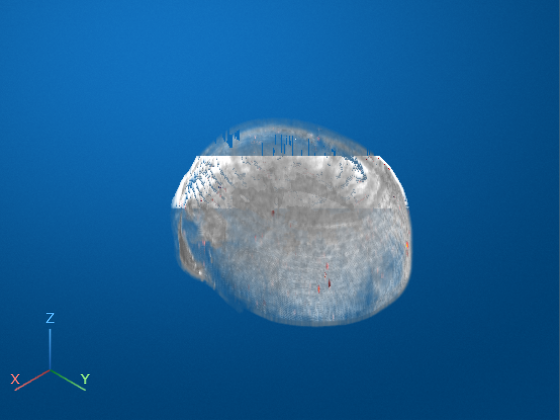

vw = viewer3d();
vx = 0.9;
vy= 0.95;
vz = 5;
voxelSize = [vx 0 0 0; 0 vy 0 0; 0 0 vz 0; 0 0 0 1];
transform = affinetform3d(voxelSize);
volshow(anah(:,:,end:-1:1), Parent=vw ,Colormap=hot,Transformation=transform);
volshow(ana(:,:,end:-1:1), Parent=vw ,Colormap=white, Alphamap="cubic", Transformation=transform);

clear ans anah mana pana fana slice val voxelSize transform vw vx vy vz x y z;

### Description of the anatomical arrangement of the activations

From the results, we can observe a significantly greater activation of the left hemisphere of the cortex, as it is primarily dominant for language in most people.

The results report a significative activation of prefrontal cortex whose subregions, such as the dorsolateral prefrontal (DLPFC) and orbitofrontal (OFC) cortices are known to have differentiable roles in cognition, including reasoning planning and decision-making [5]. In particular the DLPFC contribute more to the decision making phase, while the OFC is more involved in choice evaluation and uncertainty feedback [5]. 

We can observe a significant activation of the temporal lobe, particularly in Wernicke's area, related to language comprehension.

We see also a significant activation of the posterior cortex, specifically the occipital lobe which is the area primarily responsible for visual processing and which contains the primary and association visual  [6].

### Bibliography

*[1] Glover GH. Overview of functional magnetic resonance imaging. Neurosurg Clin N Am. 2011 Apr;22(2):133-9, vii. doi: 10.1016/j.nec.2010.11.001. PMID: 21435566; PMCID: PMC3073717.*

*[2] Madkhali Y, Aldehmi N, Pollick F. Functional Localizers for Motor Areas of the Brain Using fMRI. Comput Intell Neurosci. 2022 May 28;2022:7589493. doi: 10.1155/2022/7589493. Retraction in: Comput Intell Neurosci. 2023 Dec 13;2023:9870415. doi: 10.1155/2023/9870415. PMID: 35669664; PMCID: PMC9167083.*

*[3] K. Friston, P. Fletche, O. Josephs, A. Holmes, M. Rugg and R. Turner, “Event-related fMRI:Characterising differential responses,” Neuroimage, vol. 7, pp. 30-40, 1998.*

*[4] R. Frackowiak, K. Friston, C. Frith, R.Dolan, C. Price, S. Seki, J. Ashburner, and W. Penny, Eds., Human Brain Function, 2nd ed. Elsevier Academic Press, 2003, ch. 37.*

*[5] Demanuele C, Kirsch P, Esslinger C, Zink M, Meyer-Lindenberg A, Durstewitz D. Area-specific information processing in prefrontal cortex during a probabilistic inference task: a multivariate fMRI BOLD time series analysis. PLoS One. 2015 Aug 10;10(8):e0135424. doi: 10.1371/journal.pone.0135424. PMID: 26258487; PMCID: PMC4530897.*

*[6] Uysal, Suzan, 'The Occipital Lobes and Visual Processing', Functional Neuroanatomy and Clinical Neuroscience: Foundations for Understanding Disorders of Cognition and Behavior (New York, 2023; online edn, Oxford Academic, 20 Apr. 2023).*